Question 7) Model Perdictive Control

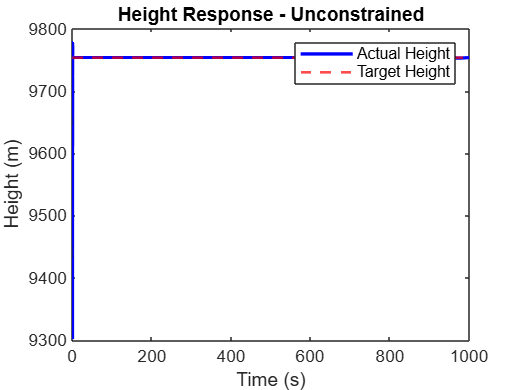

% Define the system
clear all; clc;

Hstart = 9144;
Href = 9753.6;

load('matlabData.mat','sys_mimo11')

a1 = sys_mimo11.A;
b1 = sys_mimo11.B;

b1 = b1(:,1);

select = 2; % Choose question to plot [1, 2 or 3]

% Augment system with height state
A = zeros(5,5);
A(1:4,1:4) = a1;
A(5,2) = 1; % integrate second state for height
B = [b1; 0];
C = [0 0 0 0 1]; % output is height


[K,S,P] = lqr(A, B, diag([1 1 1 1 10]), 10);
A = A - B * K;

sys_in = ss(A,B,C,0);
sys_in = -sys_in;

A = sys_in.A;
B = sys_in.B;
C = sys_in.C;

k=100;
Ts = 0.1;

ATs = zeros(5,5);
BTs = zeros(5,1);
for i = 1:k+1
    ATs = ATs + (Ts)^(i-1)*A^(i-1)./factorial(i-1);
    BTs = BTs + (A^(i-1)*Ts^(i)*B/factorial(i));
end

Am = ATs;
Bm = BTs;
Cm = C;

% MPC parameters
Np = 8;
Nc = 3;
N = 10000;
R = 0.1;

% Constraint info
NCs = 2; % how many constraints are there? (= 2 for control rate-of-change, = 2 for control magnitude, = Np for output constraint)
delU_max = 1;
delU_min = -1;
U_max = deg2rad(30);
U_min = -deg2rad(30);
y_max = Href*1.5;

x0 = zeros(6,1);
x0(end) = Hstart;
xk = x0;
xkc = x0;
xm0 = zeros(5,1);
r = Href;

% Form augmented system with integral control action
A = [Am zeros(size(Am,1),1) ; Cm*Am 1];
B = [Bm; Cm*Bm];
C = [zeros(1,size(Am,1)), 1];

sys_in_D = ss(A, B, C, 0, Ts);
sys_in_dm = ss(Am, Bm, Cm, 0, Ts);

F = zeros(Np,size(C*A,2));
Phi = zeros(Np,Nc);
for i = 1:Np
    F(i,:) = C*A^i; % form F matrix
    for j = 1:Nc
        if i-j < 0
            entry = 0;
        else
            entry = C*A^(i-j)*B;
        end
        Phi(i,j) = entry;
    end
end

Rs = r.*ones(Np,1);

Th = Phi;

M1 = Phi'*Phi;
M1 = M1+R*eye(size(M1));
Eopt = 2*M1;   % for optimisation
M1inv = M1^(-1);
M2 = Phi'*F;
M3 = Phi'*Rs;

% Compute optimal control

% Unconstrained steps first

x = x0;
xm = xm0;
y(1) = x0(end);
u(1) = 0; % Assumed initial control condition

% Data storage
Nsim = N;
dK = 0;
height_log = ones(Nsim+dK,1)*Hstart;
control_log = zeros(Nsim+dK,1);
height_logc = ones(Nsim+dK,1)*Hstart;
control_logc = zeros(Nsim+dK,1);
time = (1:Nsim-1)*Ts;

M = zeros(2,Nc);
M(1,1) = -1;
M(2,1) = 1;

Gamma = [0; 0];
Gamma(1,1) = -U_min;
Gamma(2,1) = U_max;

% Simulation loop
for k = dK+2:Nsim+dK
    % Reference signals
    Rs = (Href) * ones(Np,1);
    Rsc = (Href) * ones(Np,1);

    % Cost function
    F0  = 2*Th'*F*xk - 2*Th'*Rs;
    F0c = 2*Th'*F*xkc - 2*Th'*Rsc;
    E0  = 2*(Th'*Th + R*eye(Nc));
    invE0 = inv(E0);

    % Constrained control via Hildreth
    P0c = M * invE0 * M';
    K0c = Gamma + M * invE0 * F0c;

    lc = zeros(2,1);
    for m = 1:7
        lc(1) = max(-(K0c(1) + P0c(1,2)*lc(2)) / P0c(1,1), 0);
        lc(2) = max(-(K0c(2) + P0c(2,1)*lc(1)) / P0c(2,2), 0);
    end

    UoptC = -invE0*F0c - invE0*M'*lc;
    Uopt  = -invE0*F0;

    Uk = Uopt(1);
    Ukc = UoptC(1);

    % State updates
    xk = A*xk + B*Uk;
    xkc = A*xkc + B*Ukc;

    % Log
    height_log(k) = xk(end);
    control_log(k) = rad2deg(Uk);

    height_logc(k) = xkc(end);
    control_logc(k) = rad2deg(Ukc);
end

% Trim initial delay offset
height_log = height_log(dK+2:end);
control_log = control_log(dK+2:end);
height_logc = height_logc(dK+2:end);
control_logc = control_logc(dK+2:end);

% Plot: Unconstrained
figure;
plot(time, height_log, 'b', 'LineWidth', 2); hold on;
yline(Href, 'r--', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Height (m)');
title('Height Response - Unconstrained');
legend('Actual Height','Target Height');

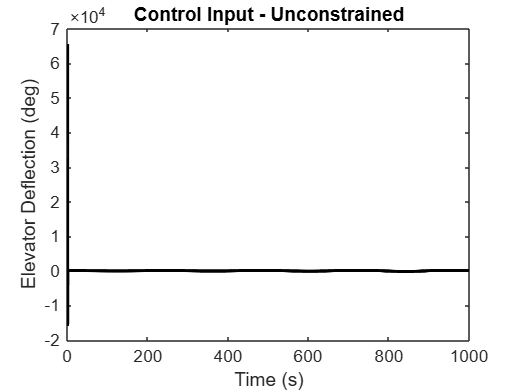


figure;
plot(time, control_log, 'k', 'LineWidth', 2); hold on;
xlabel('Time (s)'); ylabel('Elevator Deflection (deg)');
title('Control Input - Unconstrained');

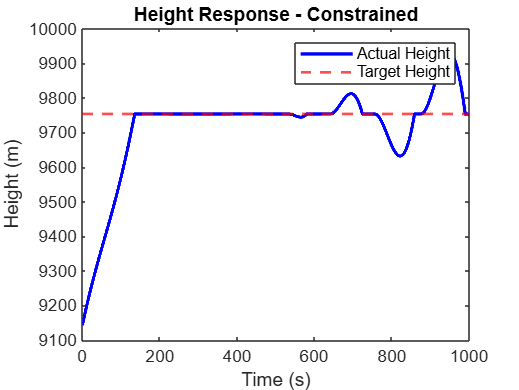


% Plot: Constrained
figure;
plot(time, height_logc, 'b', 'LineWidth', 2); hold on;
yline(Href, 'r--', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Height (m)');
title('Height Response - Constrained');
legend('Actual Height','Target Height');

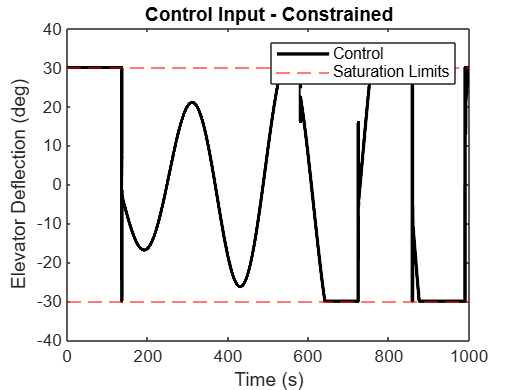


figure;
plot(time, control_logc, 'k', 'LineWidth', 2); hold on;
yline(30, 'r--'); yline(-30, 'r--');
xlabel('Time (s)'); ylabel('Elevator Deflection (deg)');
title('Control Input - Constrained');
legend('Control','Saturation Limits');